# Problema 4 - Tp7

## 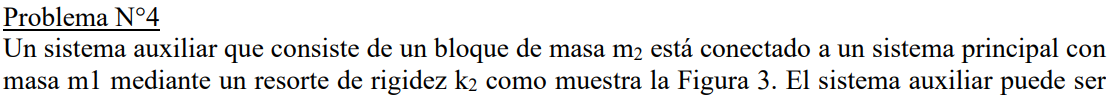

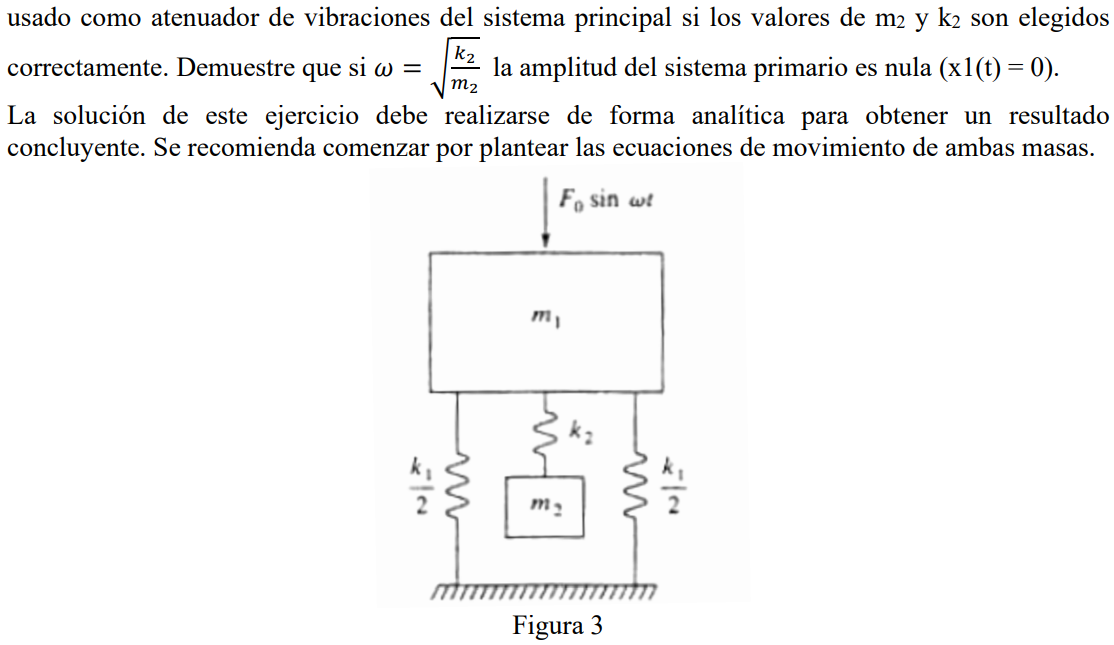

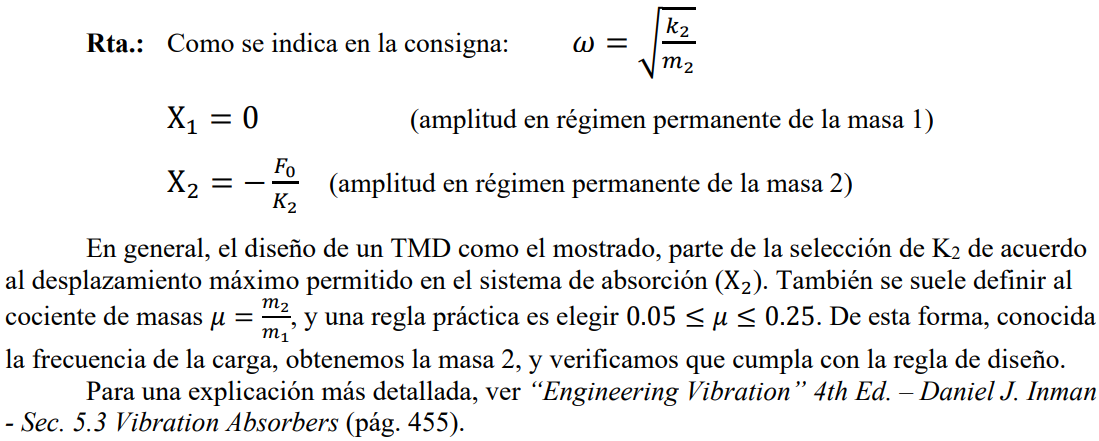

## Obtención de la matriz M y K

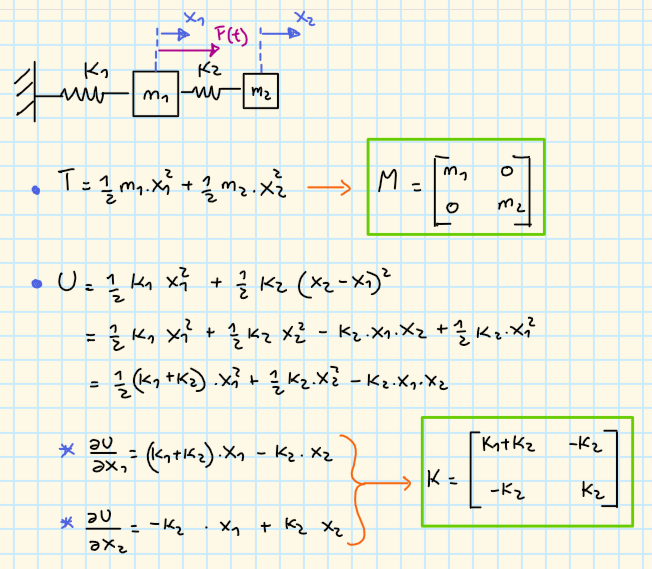

## Solución

clc; clear;

%% ---------------- DATOS DEL SISTEMA -----------------------

%Masas (seleccionadas de forma arbitraria, pero teniendo en cuenta que)
m1=100;
m2=0.1;
M = diag([m1,m2]);

Las masas se seleccionaron de forma arbitraria, pero teniendo en cuenta lo siguiente:

(al final noté que si exagero todavía más la diferencia, se ve mejor el efecto y m1 queda prácticamente inmóvil).


%Rigidez
k1=1000;
k2=3000;
K = [k1+k2 -k2;
    -k2     k2];

%Condiciones iniciales
x0 = [0; 0]; %Desplazamientos iniciales
dx0 = [0; 0] ; %Velocidades iniciales

%Tiempo para graficar
tf=2;
dt=0.01;
t=0:dt:tf;

%Relacion de amortiguamiento crítico
zitta = [0; 0];

%% ------------------ AUTOVECTORES Y AUTOVALORES ------------------

[V,lambda] = eig(K,M);
w = diag(sqrt(lambda));

%% ----------------- FUERZA ---------------------------------------
Po = 5000; %[N]
wp = sqrt(k2/m2);

%Vector fuerza
P = zeros(length(M),length(t));
P(1,:) = Po.*sin(wp*t);

%% ----------------- MATRICES MODALES -----------------------------

Mmodal = round(V' * M * V);
Kmodal = round(V' * K * V);
Y0 = V' * M * x0;                   %desplazamiento inicial en coordenadas modales
dY0 = V' * M * dx0;                 %velocidad inicial en coordenadas modales
Cmodal = 2*zitta.*w.*eye(size(M));
Pmodal = V' * P;                    %Paso fuerza a coordenadas modales
PoModal = V' * [Po; 0];             %Paso las amplitudes de las fuerzas a coordenadas modales

%% ----------------- SOLUCION A LA EDO ----------------------------

%Tenemos un sistema de tipo Mmodal*y''+Cmodal*y'+Kmodal=Pmodal
%Cuya solución es y(t) = ytransitoria + ypermanente
%PERO EL EJERCICIO PIDE SOLO EVALUAR LA RESPUESTA PERMANENTE

%la respuesta permanente es
%ypermanente = ro * cos(wp*t-phi) donde ro es la amplitud y phi es el
%angulo de atraso
%ro(j)=Fo(j)/(k(j)*sqrt( (1-beta^2)^2 + (2*zitta*beta)^2 ))
%phi(j)=atan(2*zitta*beta/(1-beta^2));

%Cosas que necesito para calcular la solucion
e=exp(1);
wd = w.*sqrt(1-zitta.^2); %frecuencia natural del sistema amortiguado
beta = zeros(length(w),1);
phi = zeros(length(w),1);
rho = zeros(length(w),1);
D = zeros(length(w),1);

for i=1:length(w)
    beta(i)=wp/w(i);
    D(i) = 1/sqrt( (1-beta(i)^2)^2 + (2*zitta(i)*beta(i))^2 );
    phi(i)=atan(2*zitta(i)*beta(i)/(1-beta(i)^2));
    rho(i)=PoModal(i)/Kmodal(i,i)*D(i);
end

Y = zeros(length(w), length(t));

for i = 1:length(w)    
    Y(i,:) = rho(i,:).*sin(wp*t-phi(i));
end


%Ahora paso de coordenadas modales a geométricas
X = V * Y;

%Analizo amplitud de m1, que debería ser proxima a cero
X1max=max(X(1,:));
X1max_Teorico = 0;
tablaX1=table(X1max, X1max_Teorico);
tablaX1.Properties.VariableNames = {'X1max', 'X1max_teórico'}

tablaX1 = 1×2 table
     X1max      X1max_teórico
    ________    _____________

    0.003329          0      




%Comparo si la amplitud máxima de m2 corresponde a -Po/k2
X2max=max(X(2,:));
X2max_Teorico = Po/k2;
tablaX2=table(X2max, X2max_Teorico);
tablaX2.Properties.VariableNames = {'X2max', 'X2max_teórico (Po/k2)'}

tablaX2 = 1×2 table
    X2max     X2max_teórico (Po/k2)
    ______    _____________________

    1.6633           1.6667        


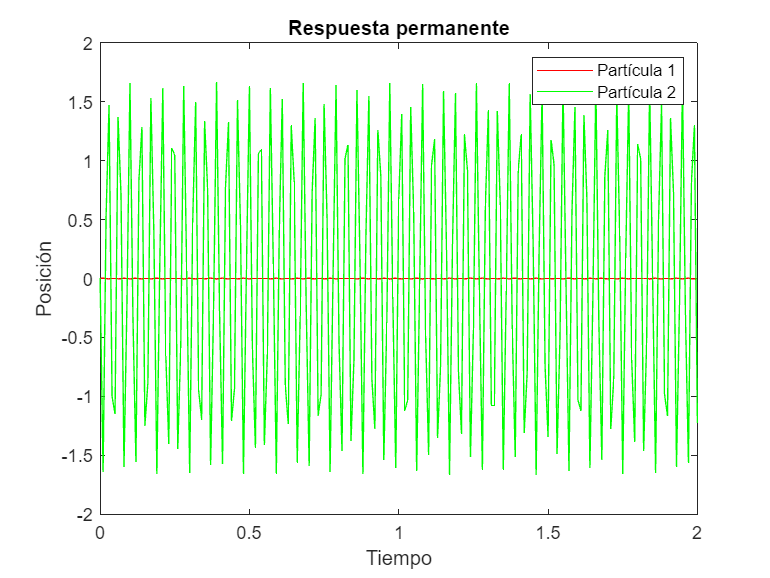



% Graficar las posiciones de las partículas
figure
plot(t, X(1,:), 'r', t, X(2,:), 'g');
xlabel('Tiempo');
ylabel('Posición');
legend('Partícula 1', 'Partícula 2');
title('Respuesta permanente');